# Putain de BAR à la con

## Adhérence

% clear all
% close all

g = 9.81; % Pesanteur (m/s²)

% Pilote
m_p = 75; % Masse du pilote (kg)
h_g_p = 0.42; % Hauteur du centre de gravite du pilote (m)

% Base roulante
m_v = 222; % Masse du vehicule (kg)
h_g_v = 0.3; % Hauteur du centre de gravite de la voiture (m)
emp = 1.575; % Empattement (m)
rep = 0.55; % Masse sur l'essieu arrière en statique (%)
m=m_v+m_p;% masse véhicule
mur=10;%masse non suspendu avant
muf=10;%masse non suspendue arrière
ms=m-mur-muf%masse suspendue

ms = 277

h_g = (m_v*h_g_v+m_p*h_g_p)/m

h_g = 0.3303

Tf=1.575;%Largeur de voie avant
Tr=1.575;%largeur de voie arrière
% Pneumatiques
% Pas de glissement
coeff_adh = 1.55;
sl =0;
coeff_roul = 0.01; % Coefficient de resistance au roulement du pneu
cx=0.665;
D_roue = 0.52; % Diametre exterieur de la roue (m)
%Suspension
Kf=15800;%raideur ressort avant N/m
Kr=12100;%raideur ressort arrièreN/m


## Modèle grossier

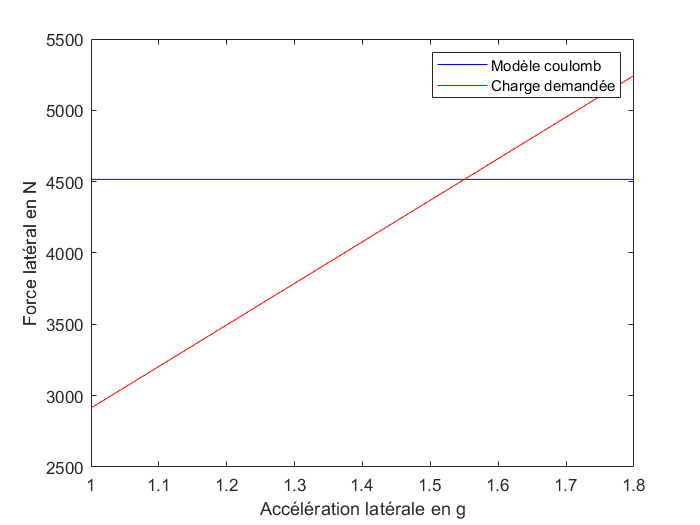

A=[1:0.05:1.8];
Fcoulomb=coeff_adh*m*g.*ones(1,length(A));
Fdemande=m.*A*g;

plot(A,Fcoulomb,'b',A,Fdemande,'r')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Modèle coulomb','Charge demandée')

## Modele AV/AR

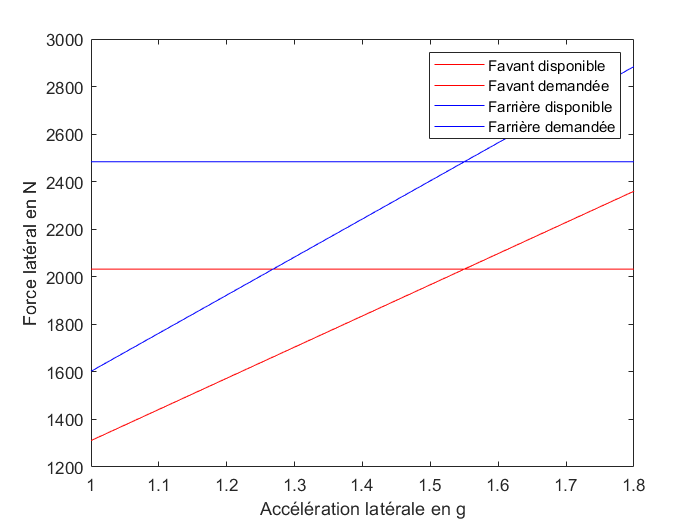

Fav=m*(1-rep).*A*g;
Far=m*rep.*A*g;
Favcoulomb=coeff_adh*m*(1-rep)*g.*ones(1,length(A));
Farcoulomb=coeff_adh*m*rep*g.*ones(1,length(A));

plot(A,Fav,'r',A,Favcoulomb,'r',A,Far,'b',A,Farcoulomb,'b')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Favant disponible','Favant demandée','Farrière disponible','Farrière demandée')

L'arrière décroche en première => sur-vireur

## Modele Raideur anti-roulis


$$F_{\phi}=$$


On prend les raideurs des suspensions de Valkiryz

## Simu Décrochage de l'avant 1 BAR à l'avant

lf = 1000*zeros(1,1);
Accel_d=zeros(1,length(lf));

for i=1:length(lf);
    a=1;
    C=m*a*g*h_g;
    Wfstat=0.5*g*(mur+ms*rep);
    DWuf=a*g*muf*D_roue/2/Tf;
    DWsff=ms*a*g*(1-rep)*h_g/Tf;
    Kphir=Tr^2*Kr/(114.6*10^3);
    Kphif=Tf^2*Kf/(114.6*10^3)+lf(i);
    DWscf=Kphif/(Kphif+Kphir)*C/Tf;
    Wf=Wfstat+DWuf+DWsff+DWscf
    while coeff_adh*Wf>m*a*g*(1-rep);
        C=m*a*g*h_g;
        DWuf=a*g*muf*D_roue/2/Tf;
        DWsff=ms*a*g*(1-rep)*h_g/Tf;
        Kphir=Tr^2*Kr/(114.6*10^3);
        Kphif=Tf^2*Kf/(114.6*10^3)+lf(i);
        DWscf=Kphif/(Kphif+Kphir)*C/Tf;
        Wf=Wfstat+DWuf+DWsff+DWscf;
        a=a+0.01;
    end
    Accel_d(i)=a
end

Wf = 1.4150e+03

Accel_d = 3.4800

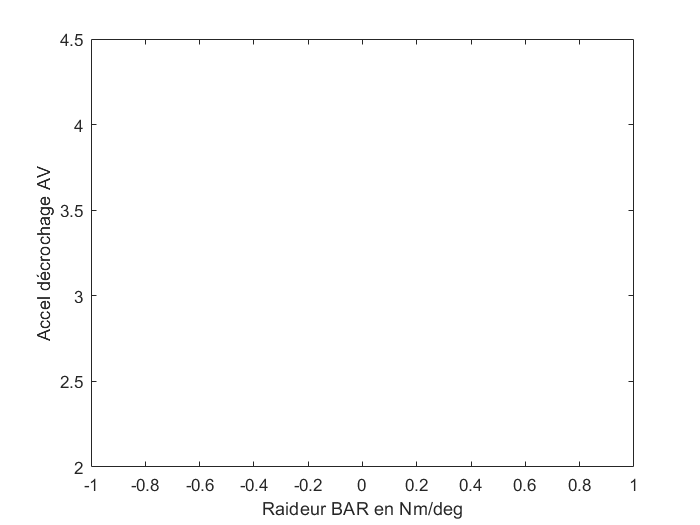

plot(lf,Accel_d)
xlabel('Raideur BAR en Nm/deg')
ylabel('Accel décrochage AV')